
% outliers and smooth para os torques do quadril direito SIMSCAPE para V1 torqQV1_SM

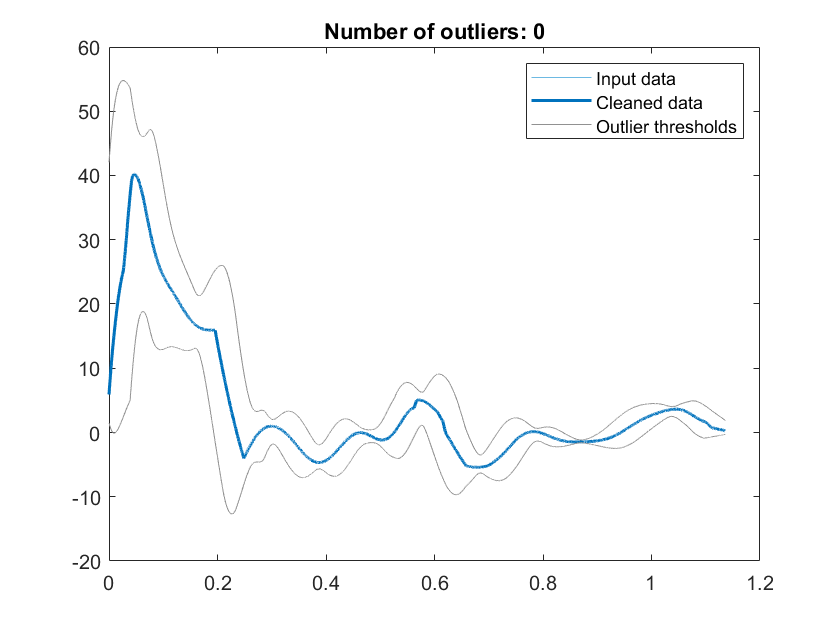

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(torqQV1_SM,'linear','movmean',0.078,'ThresholdFactor',2.5,...
    'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,torqQV1_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM1(outlierIndices),torqQV1_SM(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(tSM1(outlierIndices),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM1(:); missing; tSM1(:)],[thresholdHigh(:); missing; thresholdLow(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh

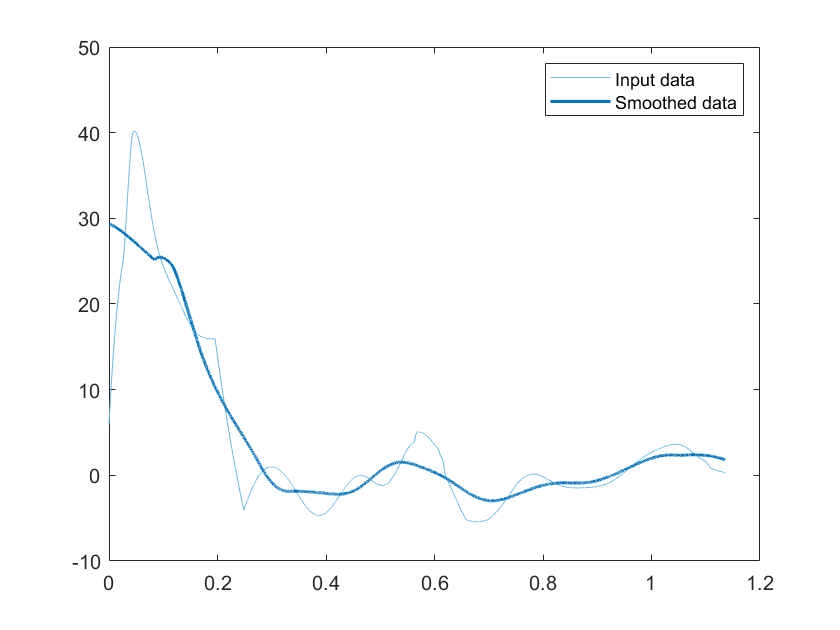

% Smooth input data
smoothedData = smoothdata(cleanedData,'movmean','SmoothingFactor',0.2,...
    'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,cleanedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do quadril direito SIMSCAPE para V2 torqQV2_SM

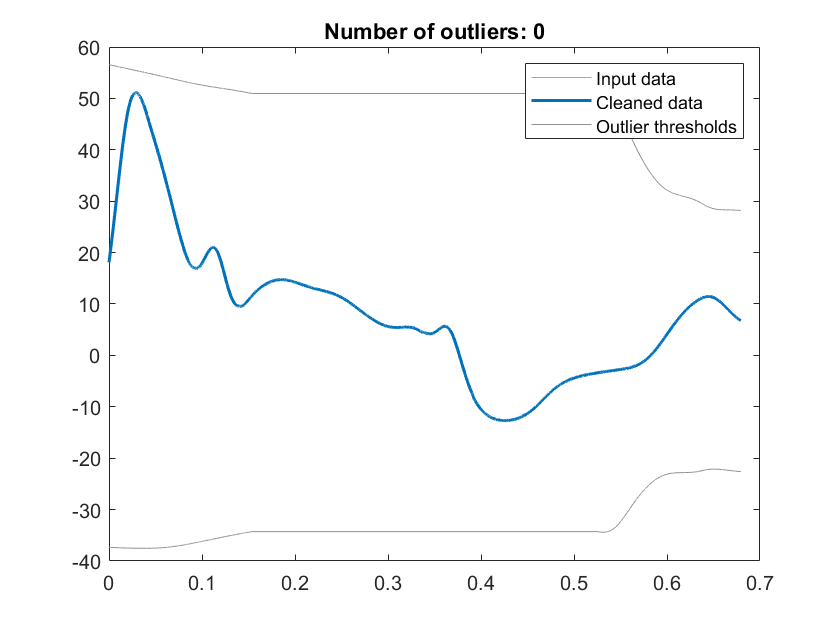

% Fill outliers
[cleanedData2,outlierIndices3,thresholdLow3,thresholdHigh3] = ...
    filloutliers(torqQV2_SM,'linear','movmean',1.05,'SamplePoints',tSM2);

% Display results
clf
plot(tSM2,torqQV2_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM2,cleanedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM2(outlierIndices3),torqQV2_SM(outlierIndices3),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices3))])

% Plot filled outliers
plot(tSM2(outlierIndices3),cleanedData2(outlierIndices3),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM2(:); missing; tSM2(:)],[thresholdHigh3(:); missing; thresholdLow3(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices3 thresholdLow3 thresholdHigh3

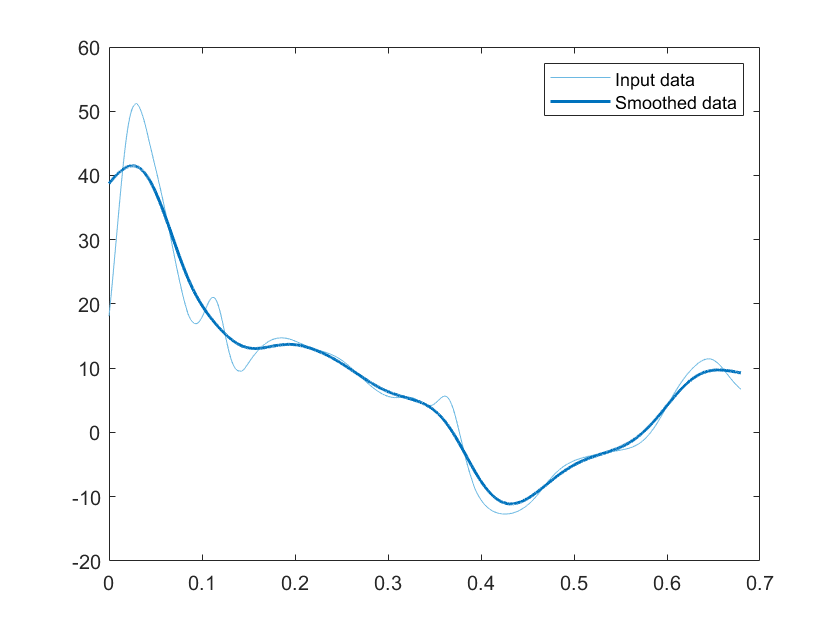

% Smooth input data
smoothedData2 = smoothdata(cleanedData2,'gaussian','SmoothingFactor',0.25,...
    'SamplePoints',tSM2);

% Display results
clf
plot(tSM2,cleanedData2,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM2,smoothedData2,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do quadril direito SIMSCAPE para V3 torqQV3_SM

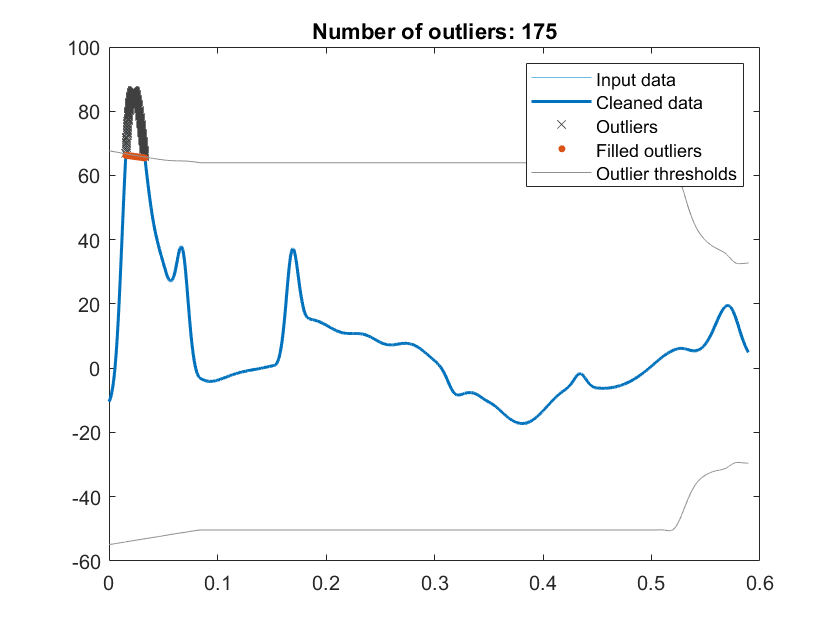

% Fill outliers
[cleanedData3,outlierIndices4,thresholdLow4,thresholdHigh4] = ...
    filloutliers(torqQV3_SM,'linear','movmean',1.011,'SamplePoints',tSM3);

% Display results
clf
plot(tSM3,torqQV3_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM3,cleanedData3,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM3(outlierIndices4),torqQV3_SM(outlierIndices4),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices4))])

% Plot filled outliers
plot(tSM3(outlierIndices4),cleanedData3(outlierIndices4),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM3(:); missing; tSM3(:)],[thresholdHigh4(:); missing; thresholdLow4(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices4 thresholdLow4 thresholdHigh4

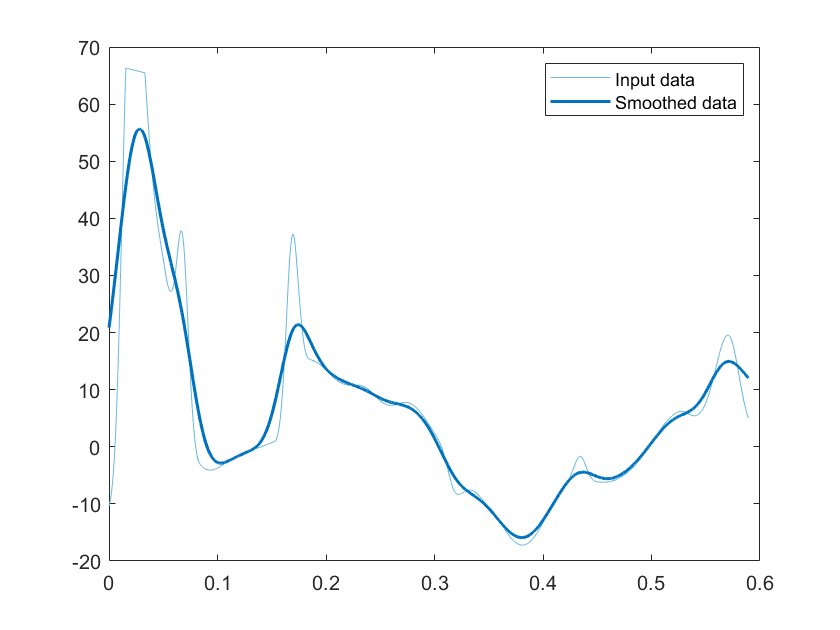

% Smooth input data
smoothedData3 = smoothdata(cleanedData3,'gaussian','SmoothingFactor',0.3,...
    'SamplePoints',tSM3);

% Display results
clf
plot(tSM3,cleanedData3,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM3,smoothedData3,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

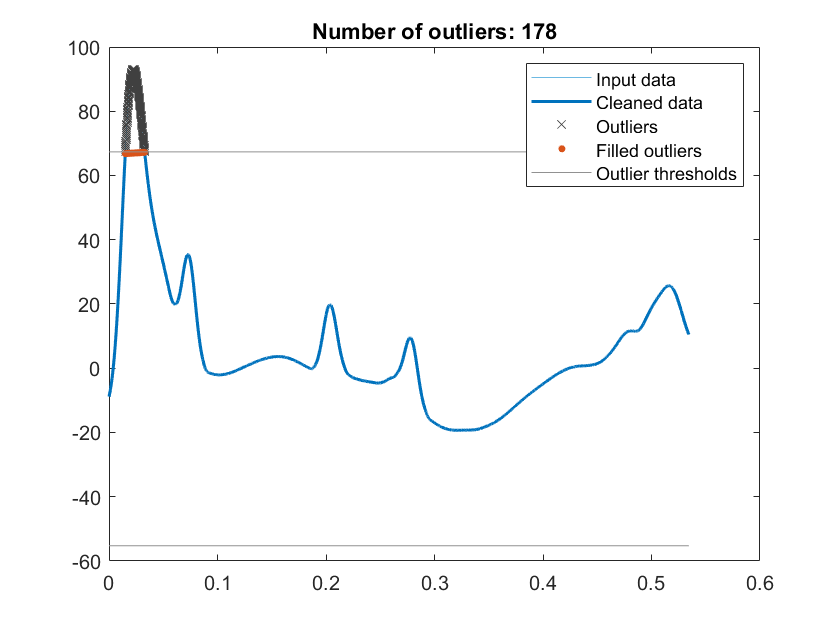

% Fill outliers
[cleanedData4,outlierIndices5,thresholdLow5,thresholdHigh5] = ...
    filloutliers(torqQV4_SM,'linear','movmean',3.004,'ThresholdFactor',2.9,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,torqQV4_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,cleanedData4,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM4(outlierIndices5),torqQV4_SM(outlierIndices5),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices5))])

% Plot filled outliers
plot(tSM4(outlierIndices5),cleanedData4(outlierIndices5),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM4(:); missing; tSM4(:)],[thresholdHigh5(:); missing; thresholdLow5(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices5 thresholdLow5 thresholdHigh5

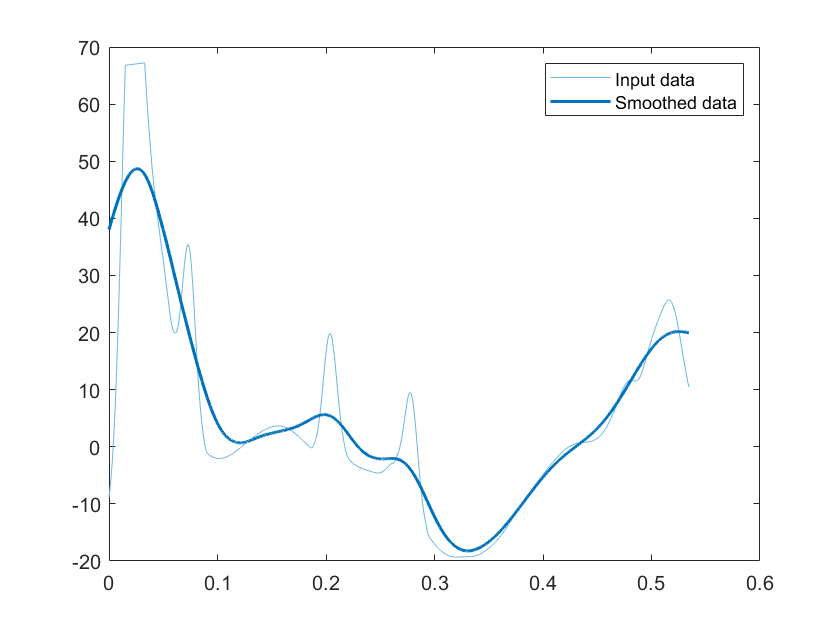

% Smooth input data
smoothedData4 = smoothdata(cleanedData4,'gaussian','SmoothingFactor',0.4,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,cleanedData4,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,smoothedData4,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do Joelho Direito SIMSCAPE para V1 torqJV1_SM

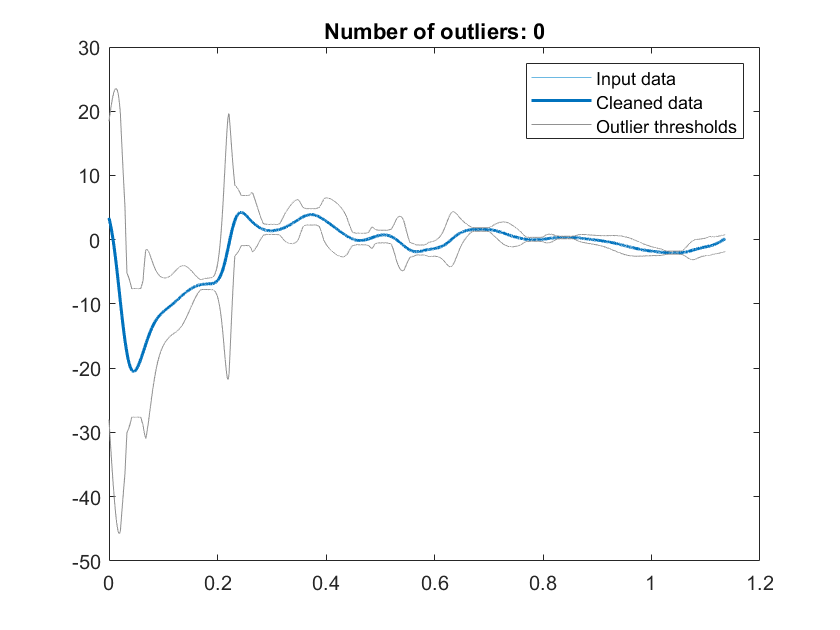

% Fill outliers
[cleanedData5,outlierIndices6,thresholdLow6,thresholdHigh6] = ...
    filloutliers(torqJV1_SM,'linear','movmedian',0.059,'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,torqJV1_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,cleanedData5,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM1(outlierIndices6),torqJV1_SM(outlierIndices6),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices6))])

% Plot filled outliers
plot(tSM1(outlierIndices6),cleanedData5(outlierIndices6),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM1(:); missing; tSM1(:)],[thresholdHigh6(:); missing; thresholdLow6(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices6 thresholdLow6 thresholdHigh6

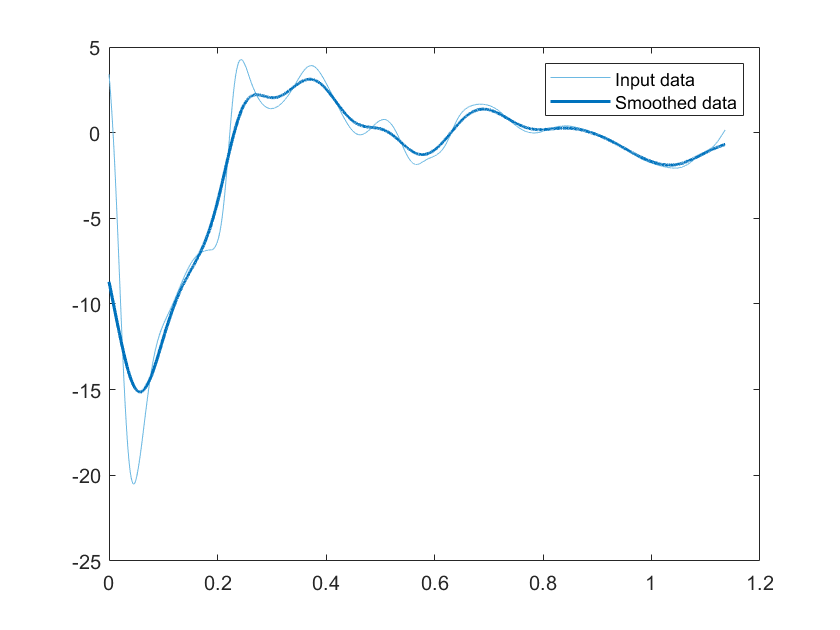

% Smooth input data
smoothedData5 = smoothdata(cleanedData5,'gaussian','SmoothingFactor',0.25,...
    'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,cleanedData5,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,smoothedData5,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do Joelho Direito SIMSCAPE para V2 torqJV2_SM

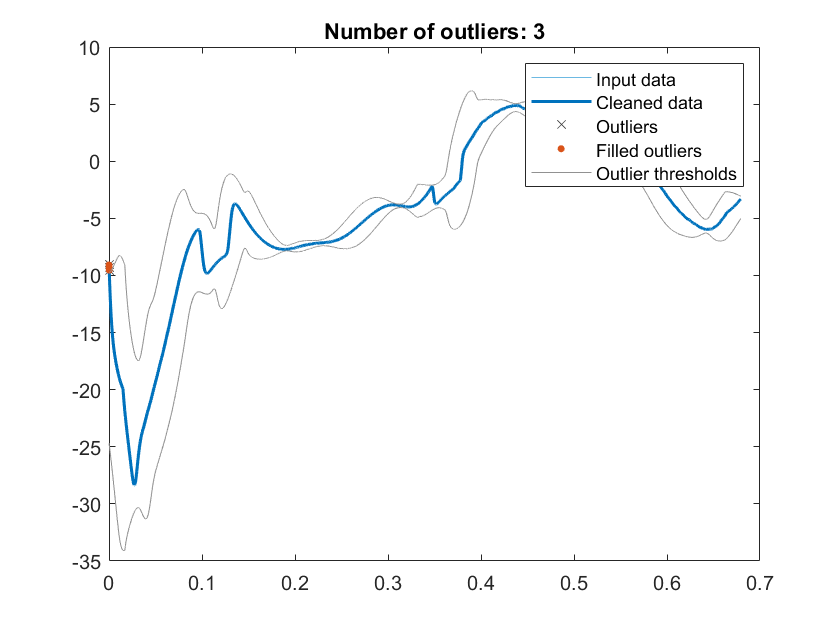

% Fill outliers
[cleanedData6,outlierIndices7,thresholdLow7,thresholdHigh7] = ...
    filloutliers(torqJV2_SM,'linear','movmean',0.034,'ThresholdFactor',2.5,...
    'SamplePoints',tSM2);

% Display results
clf
plot(tSM2,torqJV2_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM2,cleanedData6,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM2(outlierIndices7),torqJV2_SM(outlierIndices7),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices7))])

% Plot filled outliers
plot(tSM2(outlierIndices7),cleanedData6(outlierIndices7),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM2(:); missing; tSM2(:)],[thresholdHigh7(:); missing; thresholdLow7(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices7 thresholdLow7 thresholdHigh7

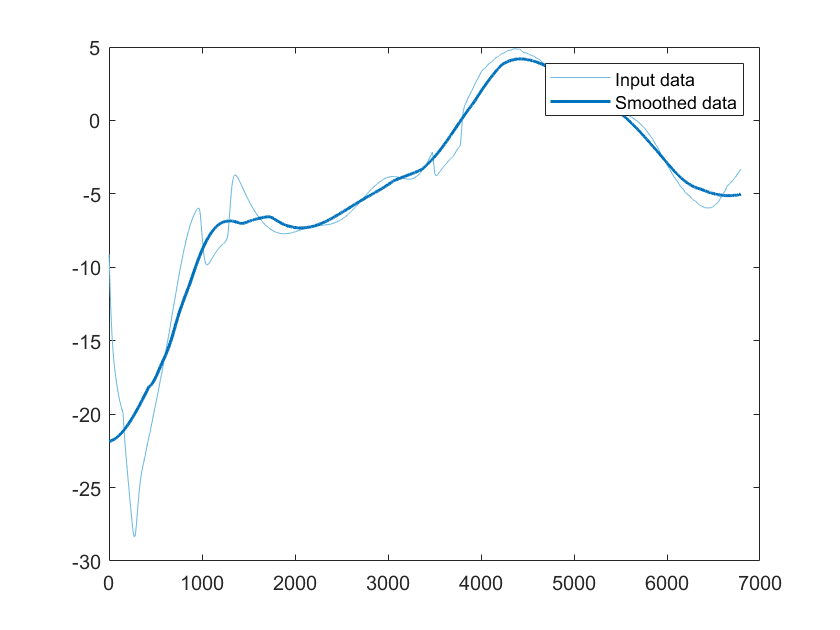

% Smooth input data
smoothedData6 = smoothdata(cleanedData6,'movmean','SmoothingFactor',0.2);

% Display results
clf
plot(cleanedData6,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData6,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do Joelho Direito SIMSCAPE para V3 torqJV3_SM

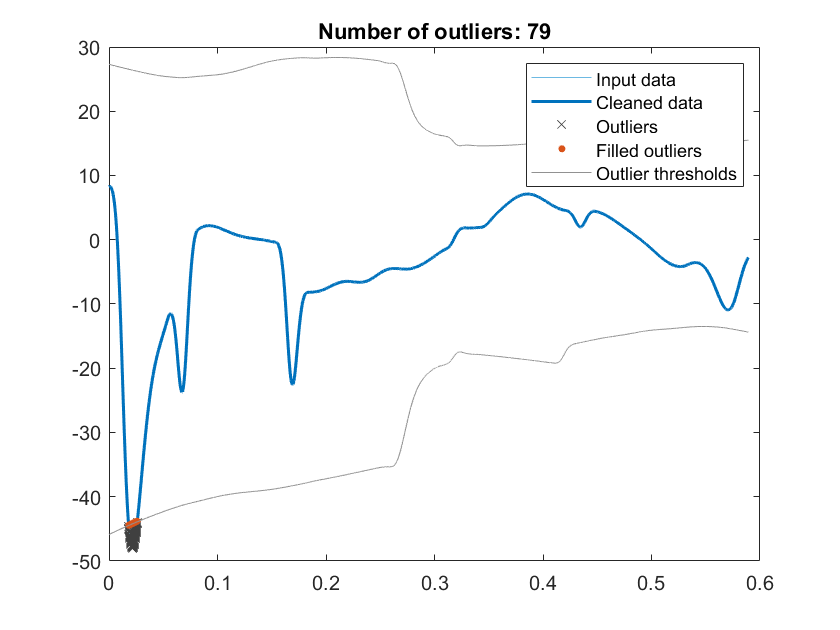

% Fill outliers
[cleanedData7,outlierIndices8,thresholdLow8,thresholdHigh8] = ...
    filloutliers(torqJV3_SM,'linear','movmean',0.5,'SamplePoints',tSM3);

% Display results
clf
plot(tSM3,torqJV3_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM3,cleanedData7,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM3(outlierIndices8),torqJV3_SM(outlierIndices8),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices8))])

% Plot filled outliers
plot(tSM3(outlierIndices8),cleanedData7(outlierIndices8),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM3(:); missing; tSM3(:)],[thresholdHigh8(:); missing; thresholdLow8(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices8 thresholdLow8 thresholdHigh8

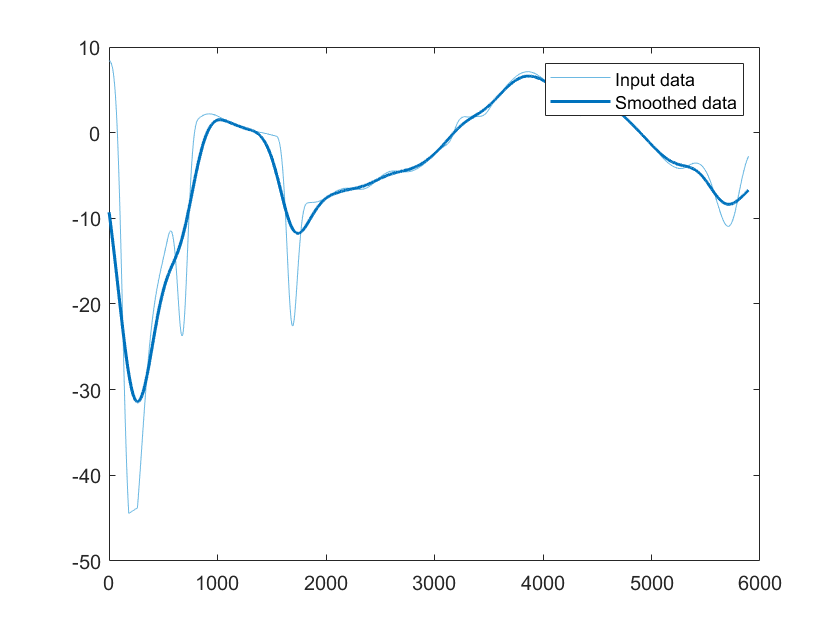

% Smooth input data
smoothedData7 = smoothdata(cleanedData7,'gaussian','SmoothingFactor',0.35);

% Display results
clf
plot(cleanedData7,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData7,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

% outliers and smooth para os torques do Joelho Direito SIMSCAPE para V4 torqJV4_SM

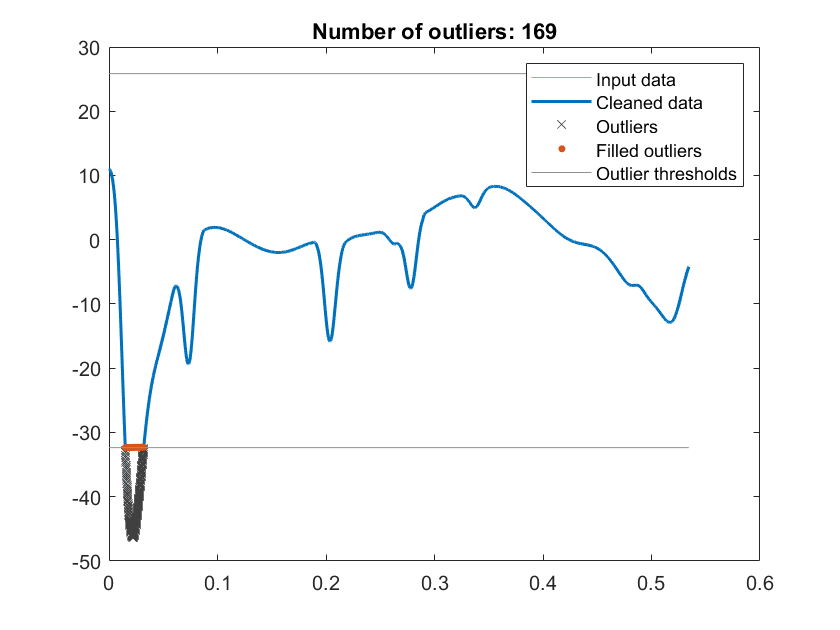

% Fill outliers
[cleanedData8,outlierIndices9,thresholdLow9,thresholdHigh9] = ...
    filloutliers(torqJV4_SM,'linear','movmean',2.004,'ThresholdFactor',2.9,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,torqJV4_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,cleanedData8,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM4(outlierIndices9),torqJV4_SM(outlierIndices9),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices9))])

% Plot filled outliers
plot(tSM4(outlierIndices9),cleanedData8(outlierIndices9),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM4(:); missing; tSM4(:)],[thresholdHigh9(:); missing; thresholdLow9(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices9 thresholdLow9 thresholdHigh9

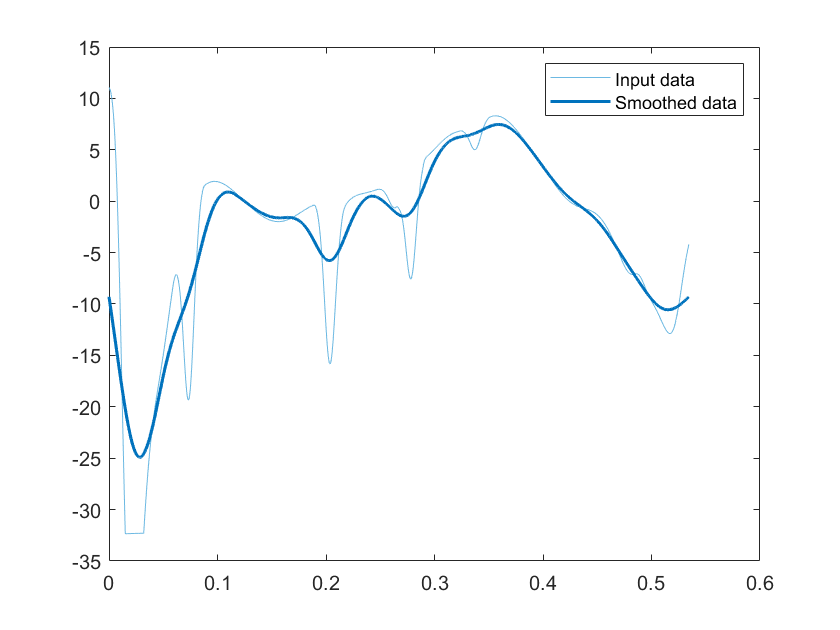

% Smooth input data
smoothedData8 = smoothdata(cleanedData8,'gaussian','SmoothingFactor',0.4,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,cleanedData8,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,smoothedData8,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

 % outliers and smooth para os torques do Quadril Direito SIMSCAPE para V1 torqTV1_SM

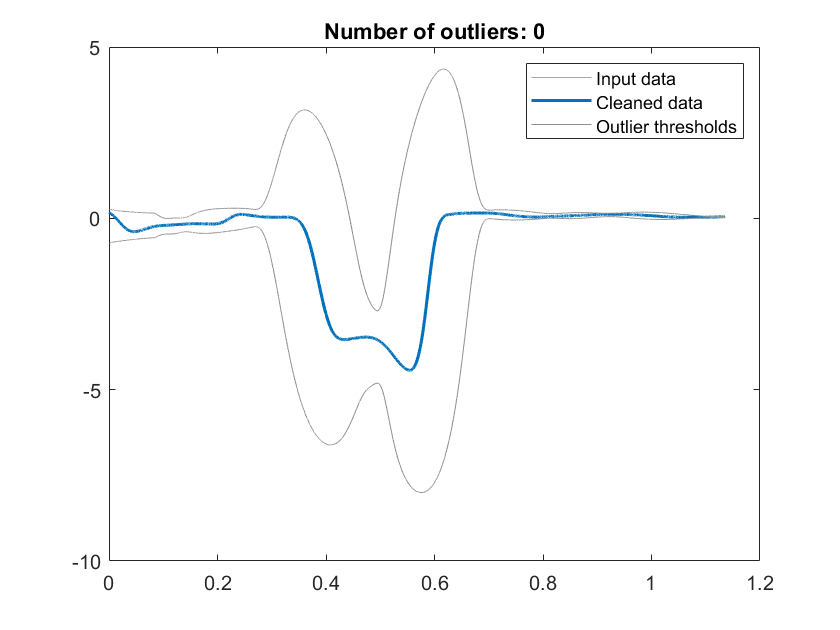

% Fill outliers
[cleanedData9,outlierIndices10,thresholdLow10,thresholdHigh10] = ...
    filloutliers(torqTV1_SM,'linear','movmean',0.17,'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,torqTV1_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,cleanedData9,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM1(outlierIndices10),torqTV1_SM(outlierIndices10),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices10))])

% Plot filled outliers
plot(tSM1(outlierIndices10),cleanedData9(outlierIndices10),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM1(:); missing; tSM1(:)],[thresholdHigh10(:); missing; thresholdLow10(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices10 thresholdLow10 thresholdHigh10

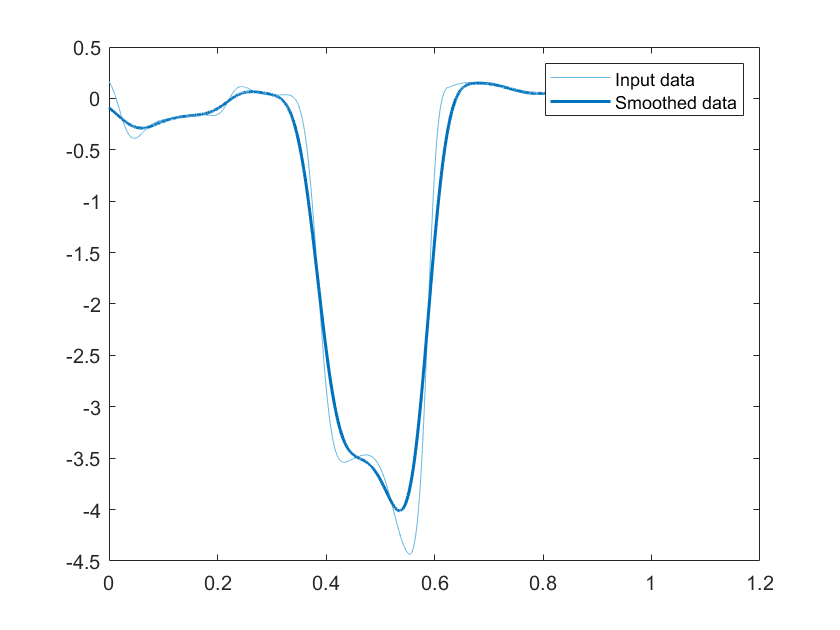

% Smooth input data
smoothedData9 = smoothdata(cleanedData9,...
    'gaussian','SmoothingFactor',0.09999999999999998,'SamplePoints',tSM1);

% Display results
clf
plot(tSM1,cleanedData9,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM1,smoothedData9,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

 
% outliers and smooth para os torques do Quadril Direito SIMSCAPE para V2 torqTV2_SM

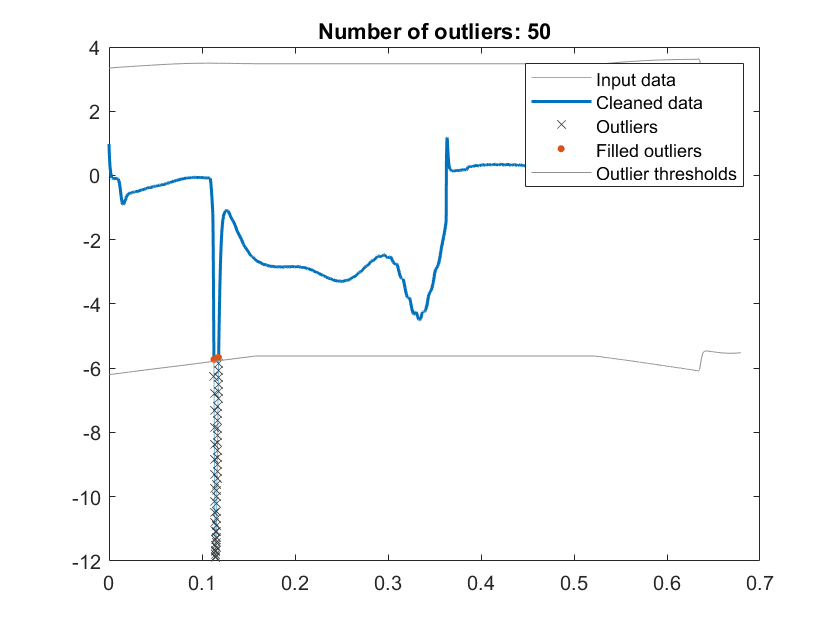

% Fill outliers
[cleanedData11,outlierIndices11,thresholdLow11,thresholdHigh11] = ...
    filloutliers(torqTV2_SM,'linear','movmean',1.043,'ThresholdFactor',2.75,...
    'SamplePoints',tSM2);

% Display results
clf
plot(tSM2,torqTV2_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM2,cleanedData11,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM2(outlierIndices11),torqTV2_SM(outlierIndices11),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices11))])

% Plot filled outliers
plot(tSM2(outlierIndices11),cleanedData11(outlierIndices11),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM2(:); missing; tSM2(:)],[thresholdHigh11(:); missing; thresholdLow11(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices11 thresholdLow11 thresholdHigh11

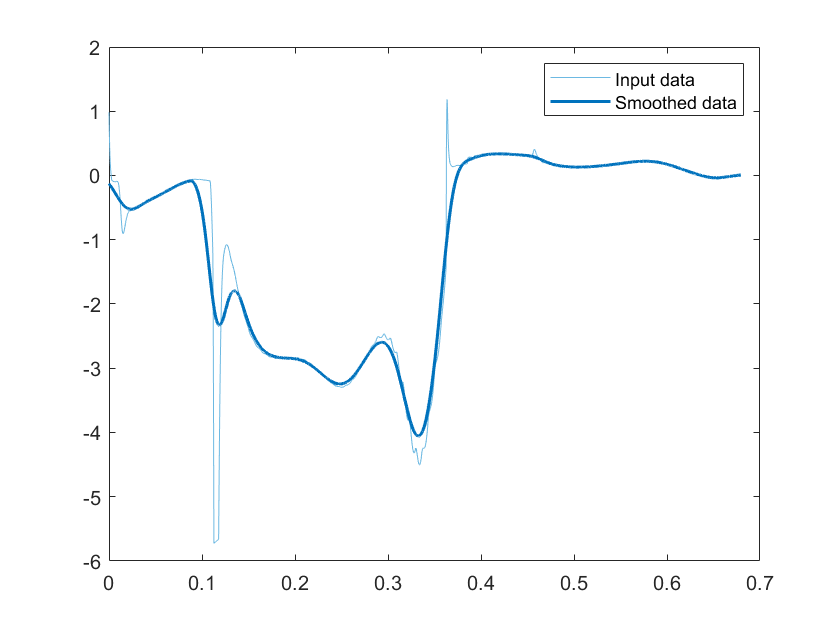

% Smooth input data
smoothedData10 = smoothdata(cleanedData11,'gaussian','SmoothingFactor',0.15,...
    'SamplePoints',tSM2);

% Display results
clf
plot(tSM2,cleanedData11,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM2,smoothedData10,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

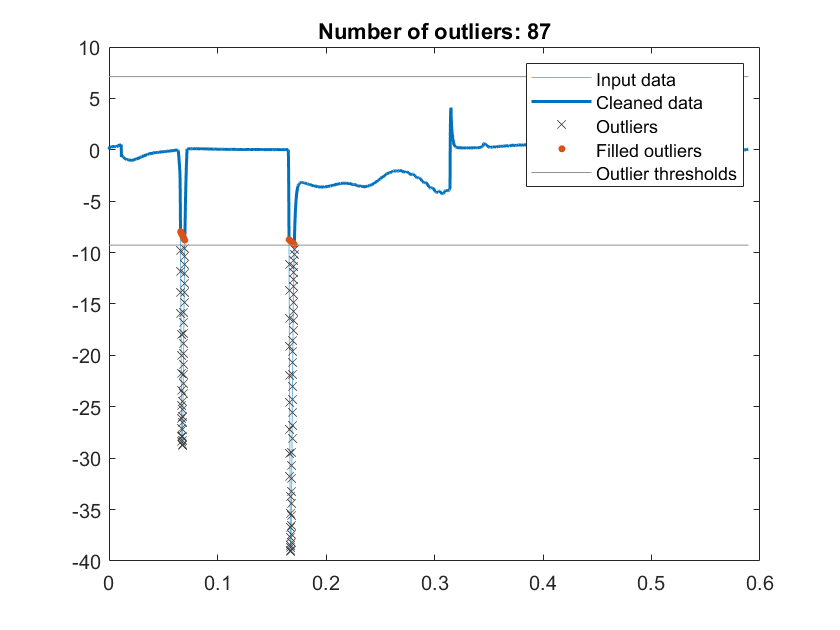

% Fill outliers
[cleanedData10,outlierIndices12,thresholdLow12,thresholdHigh12] = ...
    filloutliers(torqTV3_SM,'linear','movmean',2.005,'ThresholdFactor',2.5,...
    'SamplePoints',tSM3);

% Display results
clf
plot(tSM3,torqTV3_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM3,cleanedData10,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM3(outlierIndices12),torqTV3_SM(outlierIndices12),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices12))])

% Plot filled outliers
plot(tSM3(outlierIndices12),cleanedData10(outlierIndices12),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM3(:); missing; tSM3(:)],[thresholdHigh12(:); missing; thresholdLow12(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices12 thresholdLow12 thresholdHigh12


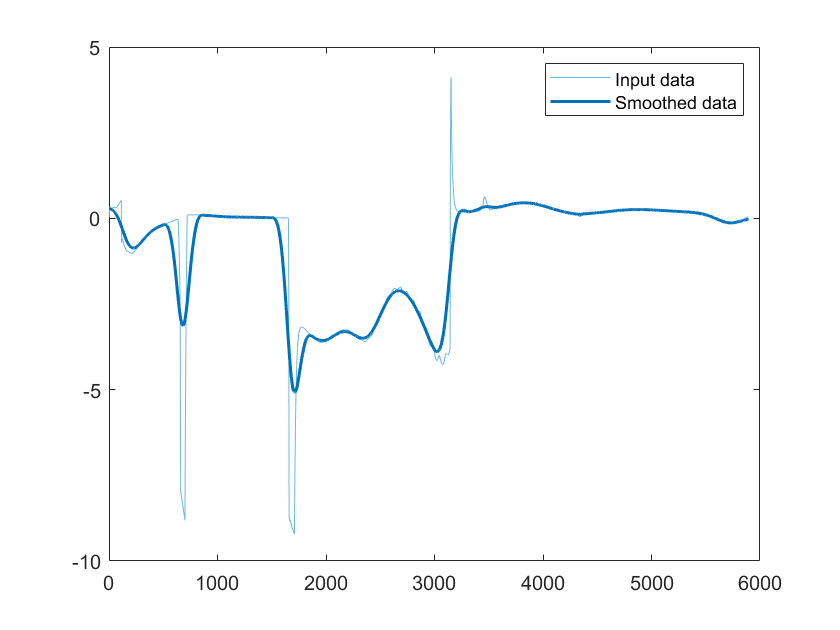

% Smooth input data
smoothedData11 = smoothdata(cleanedData10,'gaussian','SmoothingFactor',0.35);

% Display results
clf
plot(cleanedData10,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData11,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

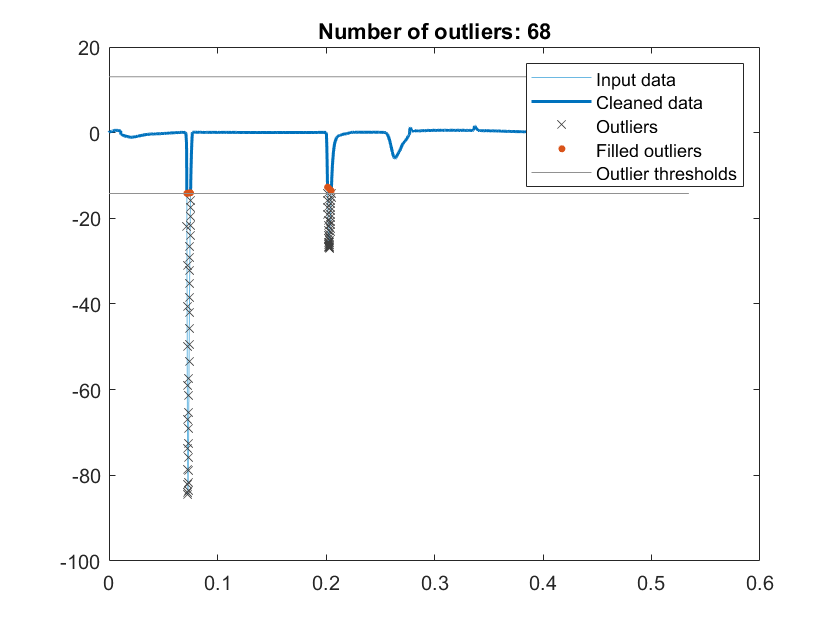

% Fill outliers
[cleanedData12,outlierIndices13,thresholdLow13,thresholdHigh13] = ...
    filloutliers(torqTV4_SM,'linear','movmean',2.0033,'ThresholdFactor',2.75,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,torqTV4_SM,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,cleanedData12,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(tSM4(outlierIndices13),torqTV4_SM(outlierIndices13),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices13))])

% Plot filled outliers
plot(tSM4(outlierIndices13),cleanedData12(outlierIndices13),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([tSM4(:); missing; tSM4(:)],[thresholdHigh13(:); missing; thresholdLow13(:)],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices13 thresholdLow13 thresholdHigh13

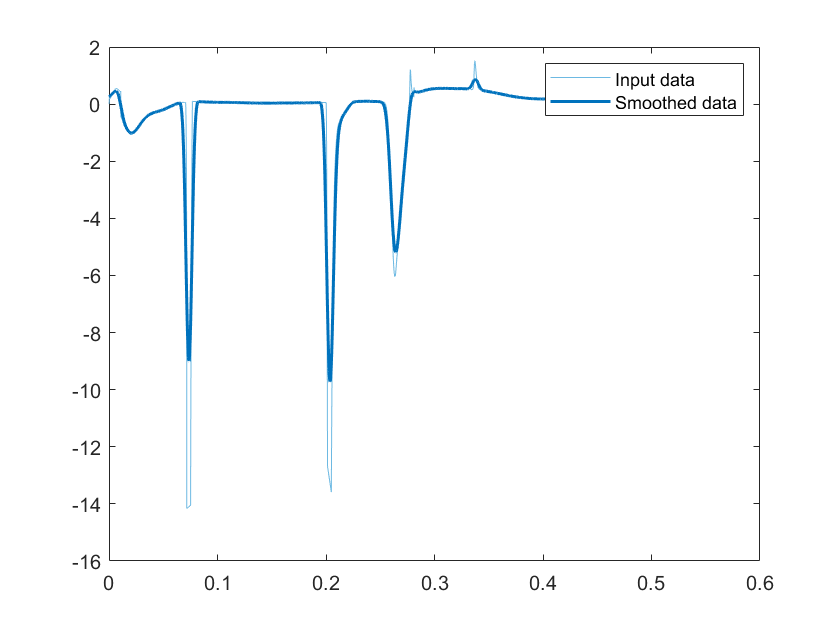

% Smooth input data
smoothedData12 = smoothdata(cleanedData12,'gaussian','SmoothingFactor',0.5,...
    'SamplePoints',tSM4);

% Display results
clf
plot(tSM4,cleanedData12,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(tSM4,smoothedData12,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend